# **Software-defined Radio Demo: BMOCZ-based OFDM**

**Description:** In this demo, we transmit and receive 1 Kilobyte of data using SDRs and a hybrid BMOCZ-based OFDM waveform. The implemented waveform is pilot-free, with synchronization, carrier frequency offset (CFO) correction, timing offset (TO) correction, and decoding performed in a "blind" manner.

The demo uses ADALM-PLUTO SDRs equipped with an AD9363 RF front end. 

**Before starting:** ensure that your working directory is the "\sdrDemo" folder and that the ADALM-PLUTO SDRs are connected to your device. 

- Note: for reasons of device identification, the PLUTO SDR used for transmit must be connected before the PLUTO SDR used for receive.

Add the "\functions" folder to your MATLAB path.

clear; close all; clc;

% Get current path and parent directory
currentFolder = pwd;
parentFolder = fileparts(currentFolder);

% Add functions to current path
addpath(strcat(parentFolder, '\functions'))

Load approximately 1 Kilobtye of data to transmit.

load bitsTX.mat
Nbits = numel(bitsTX);
Nbytes = Nbits / 8

Nbytes = 997.7500

Set the SDR, BMOCZ, and OFDM system parameters. 

This example uses a (127,106)-BCH code and, hence, we set $\texttt{B}=106$ and $\texttt{K}=127$.

% SDR parameters
fc = 910e6;   % carrier frequency 
fs = 20e6;    % sample rate
Ts = 1 / fs;  % sample time

% BMOCZ parameters
B = 106;                   % Number of bits per polynomial
K = 127;                   % Number of zeros
Rh = sqrt(1 + sin(pi/K));  % Huffmam BMOCZ radius
Rj = 1.018;                % J-BMOCZ radius
zeta = 1.04;               % Asymmetry factor

% OFDM parameters
Nidft = 512;          % IDFT size 
Ncp = 16;             % CP size
Fs = fs / Nidft;      % Subcarrier spacing 
Tsym = 1 / Fs;        % Symbol duration
Tcp = Ncp / fs;       % CP duration
S = K + 1;            % Number of active subcarriers
M = ceil(Nbits / B);  % Number of payload OFDM symbols
W = (S + 1) * Fs;     % Bandiwdth
k = 2:K+2;            % Subcarrier indices

Prepare and encode the data.

% Generate all zeros
huffmanZeros = generateAllZeros(K, Rh, 1);
jbmoczZeros = generateAllZeros(K, Rj, zeta);

% Get template matrix (Toeplitz)
[tN, tNmat] = getTemplate(jbmoczZeros, K+1, Nidft);

% Reshape TX bits
NbitsPad = B - mod(Nbits, B);
bitsTXpadded = [bitsTX; zeros(NbitsPad, 1)];
mTX = reshape(bitsTXpadded, B, []);

% (127,106)-BCH encoding
cTX = bchenc(gf(mTX.'), K, B);
cTX = double(cTX.x).';

Prepare the TX signal. 

The synchronization symbol and payload use Huffman BMOCZ, while the timing symbol employs J-BMOCZ.

% Load syncrhonization (header data)
load mTXsync.mat
Ksync = floor(K/2);
Rsync = sqrt(1 + sin(pi/Ksync));
syncZeros = generateAllZeros(Ksync, Rsync, 1);

% Generate synchronization polynomial (Huffman BMOCZ)
[polyTXsync, zerosTXsync] = jbmoczMessageToPoly(mTXsync, Rsync, 1, K+1);
polyTXsyncUp = upsample(polyTXsync, 2);

% Generate timing polynomial (J-BMOCZ)
[polyTXtiming, zerosTXtiming] = jbmoczMessageToPoly(cTX(:, 1), Rj, zeta, K+1);

% Generate payload polynomials (Huffman BMOCZ)
[polyTXpayload, zerosTXpayload] = jbmoczMessageToPoly(cTX(:, 2:end), Rh, 1, K+1);

% Scramble the payload coefficients (this avoids spikes in the PSD)
scrambleIndices = ones(K+1, M-1);
for m = 1:M-1

    % Get random permutation of indices
    indices = randperm(K+1);
    scrambleIndices(:, m) = indices;

    % Perform scrambling
    polyTXpayload(:, m) = polyTXpayload(indices, m);

end

% Subcarrier mapper (FM)
symbolsMappedTX = zeros(Nidft, M+1);
symbolsMappedTX(1:K+1, 1) = polyTXsyncUp;
symbolsMappedTX(mod(k, Nidft) + 1, 2) = polyTXtiming;
symbolsMappedTX(mod(k, Nidft) + 1, 3:end) = polyTXpayload;

% Take IDFT and add CP
X = ifft(symbolsMappedTX, Nidft);
XwithCP = [X(end-Ncp+1:end, :); X];

% Vectorize and normalize
xOFDM = XwithCP(:);
IQdataTX = xOFDM / max(abs(xOFDM));

Plot the TX signal and label the consituent OFDM symbols.

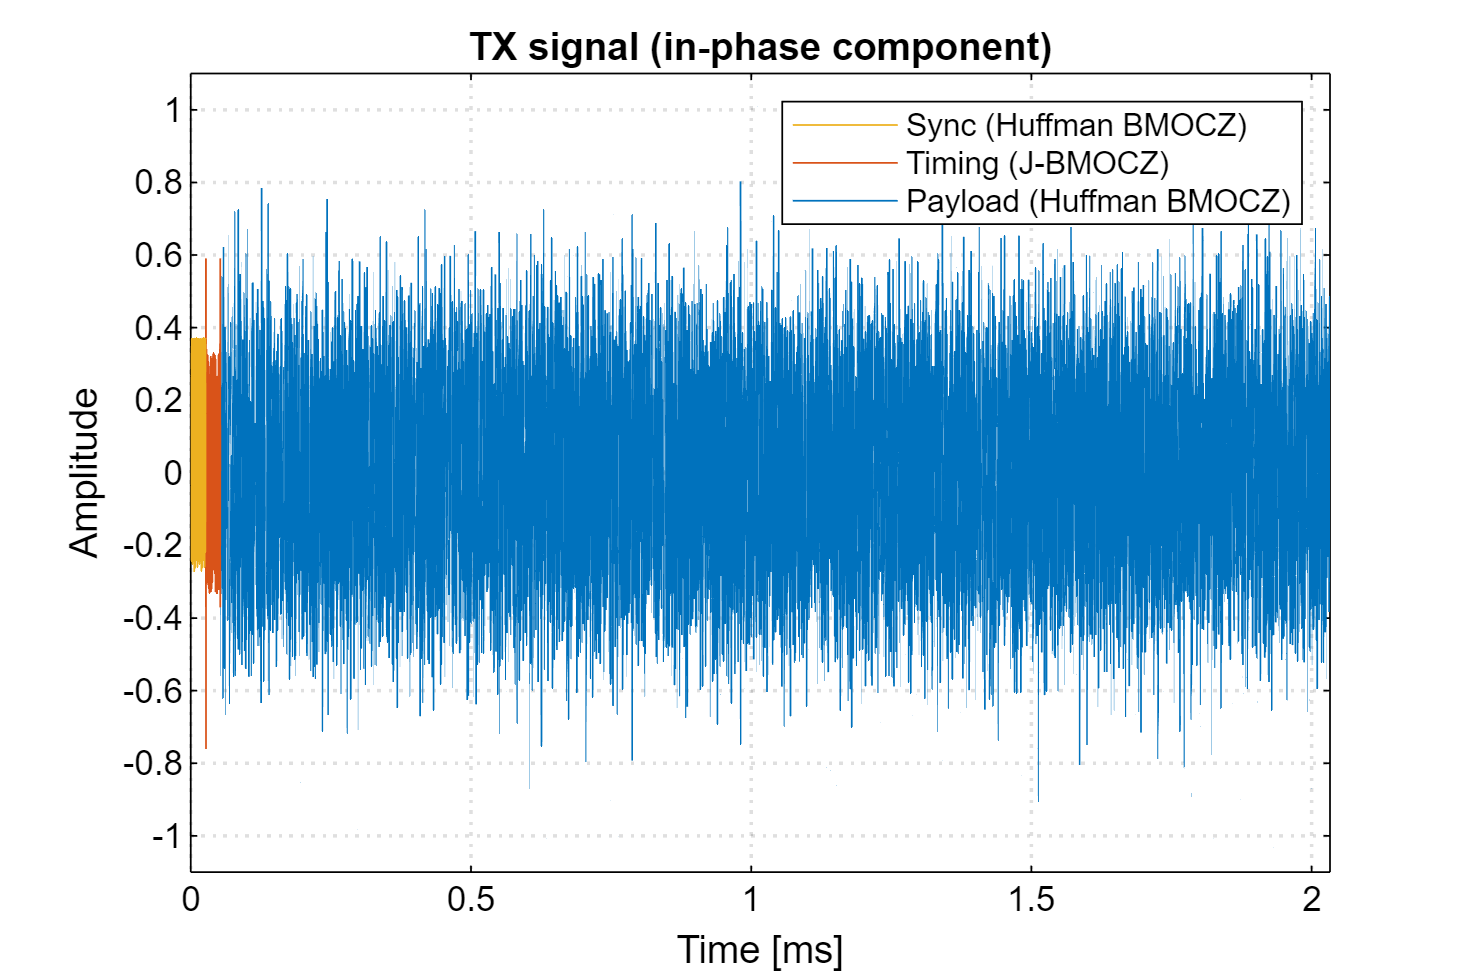

% Partition symbols (for labeling purposes)
Nsymbol = Nidft + Ncp;

t = (0:numel(IQdataTX)-1) / fs;
syncSamples = 1:Nsymbol;

tSync = t(syncSamples);
xSync = IQdataTX(syncSamples);

tTiming = t(Nsymbol:(Nsymbol+1)+Nsymbol);
xTiming = IQdataTX(Nsymbol:(Nsymbol+1)+Nsymbol);

tPayload = t((Nsymbol+1)+Nsymbol:end);
xPayload = IQdataTX((Nsymbol+1)+Nsymbol:end);

% Plot the TX signal in time domain
figure;
grid on; box on; hold on;
ax = gca; ax.GridLineStyle = ':'; ax.GridLineWidth = 1;

p1 = plot(tPayload*1e3, real(xPayload));
p2 = plot(tTiming*1e3, real(xTiming));
p3 = plot(tSync*1e3, real(xSync));

xlabel('Time [ms]')
ylabel('Amplitude')

xlim([min(t), max(t)]*1e3)
ylim([-1.1, 1.1])

legend([p3, p2, p1], {'Sync (Huffman BMOCZ)', 'Timing (J-BMOCZ)', 'Payload (Huffman BMOCZ)'});

title('TX signal (in-phase component)')

Continuously transmit the waveform using an ADALM-PLUTO SDR.

% TX parameters
txPluto = sdrtx('Pluto', ...
                'Gain', -5, ...
                'CenterFrequency', fc, ...
                'BasebandSampleRate', fs, ...
                'RadioID', 'usb:0');

% Transmit and repeat
txPluto.ShowAdvancedProperties = true;
transmitRepeat(txPluto, IQdataTX)

## Establishing connection to hardware. This process can take several seconds.


## Waveform transmission has started successfully and will repeat indefinitely. 
## Call the release method to stop the transmission.


Capture the TX signal with another ADALM-PLUTO SDR.

NsamplesCapture = 2*length(IQdataTX); % Number of samples to acquire

% RX parameters
rxPluto = sdrrx('Pluto', ...
                'RadioID', 'usb:1', ...
                'GainSource', 'Manual', ...
                'Gain', 12, ...
                'CenterFrequency', fc, ...
                'OutputDataType', 'double', ...
                'EnableBurstMode', false, ...
                'SamplesPerFrame', NsamplesCapture, ...
                'BasebandSampleRate', fs, ...
                'UseCustomFilter', false, ...
                'RadioID', 'usb:1');

% Receive signal 
IQdataRX = rxPluto();

## Establishing connection to hardware. This process can take several seconds.


Halt transmission and plot the RX signal in the time domain.

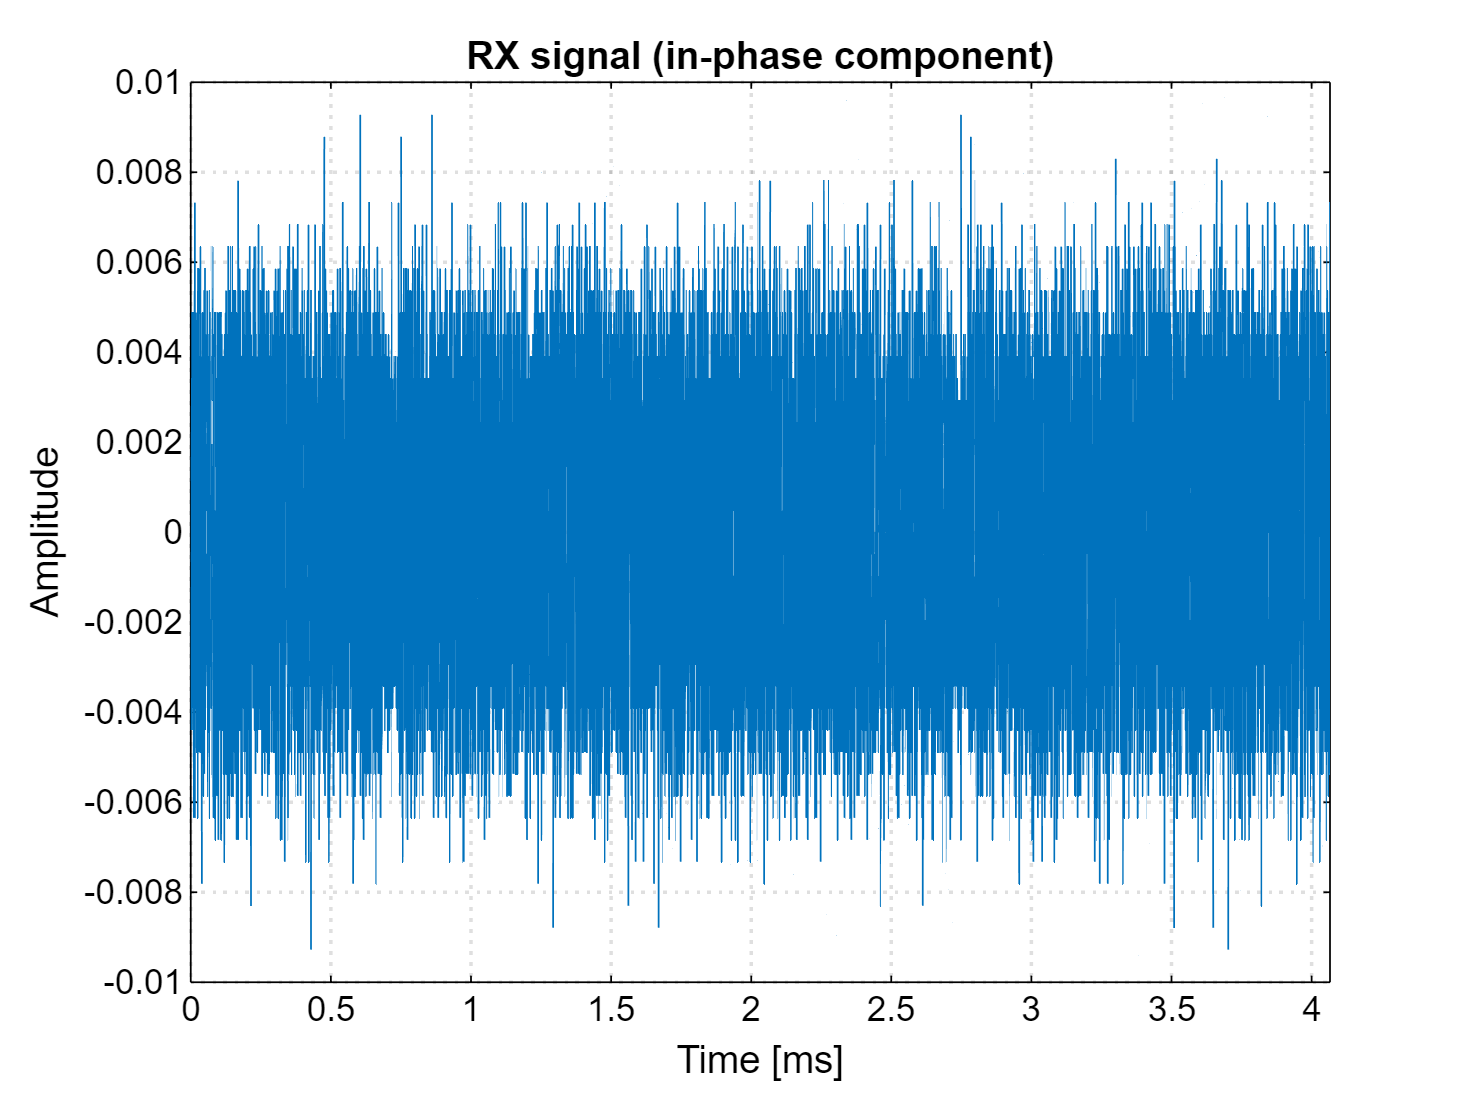

% Stop transmission
release(txPluto);

% Plot the RX signal in time domain
t = (0:numel(IQdataRX)-1) * Ts;

figure;
grid on; box on; hold on;
ax = gca; ax.GridLineStyle = ':'; ax.GridLineWidth = 1;

plot(t*1e3, real(IQdataRX))

xlabel('Time [ms]')
ylabel('Amplitude')

xlim([0, max(t)]*1e3)

title('RX signal (in-phase component)')

Calculate and plot the PSD of the TX and RX waveforms.

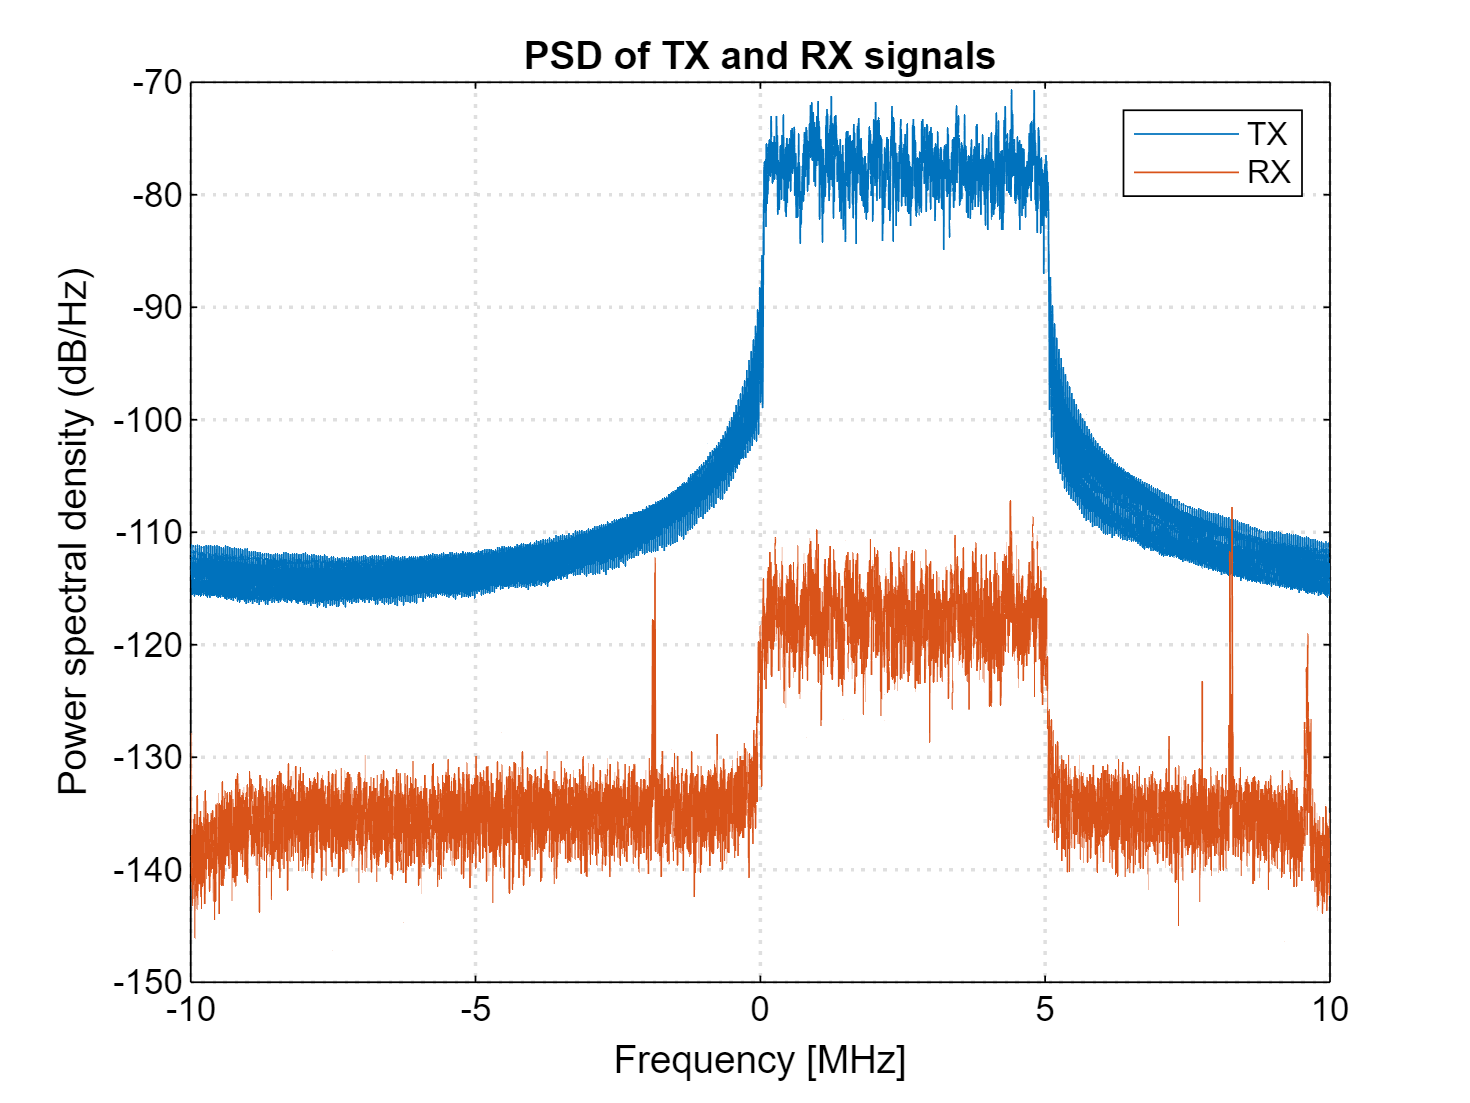

% Calculate TX PSD
[PxxTX, fTX] = pwelch(IQdataTX, [], [], [], fs, 'centered');
PxxTXdB = 10*log10(PxxTX);

% Calculate RX PSD
[PxxRX, fRX] = pwelch(IQdataRX, [], [], [], fs, 'centered');
PxxRXdB = 10*log10(PxxRX);

% Plot TX/RX PSD
figure;
grid on; box on; hold on;
ax = gca; ax.GridLineStyle = ':'; ax.GridLineWidth = 1;

plot(fTX/1e6, PxxTXdB)
plot(fRX/1e6, PxxRXdB)

xlabel('Frequency [MHz]')
ylabel('Power spectral density (dB/Hz)')

legend({'TX', 'RX'});

title('PSD of TX and RX signals')

Perform coarse syncrhonization and plot the correlator output.

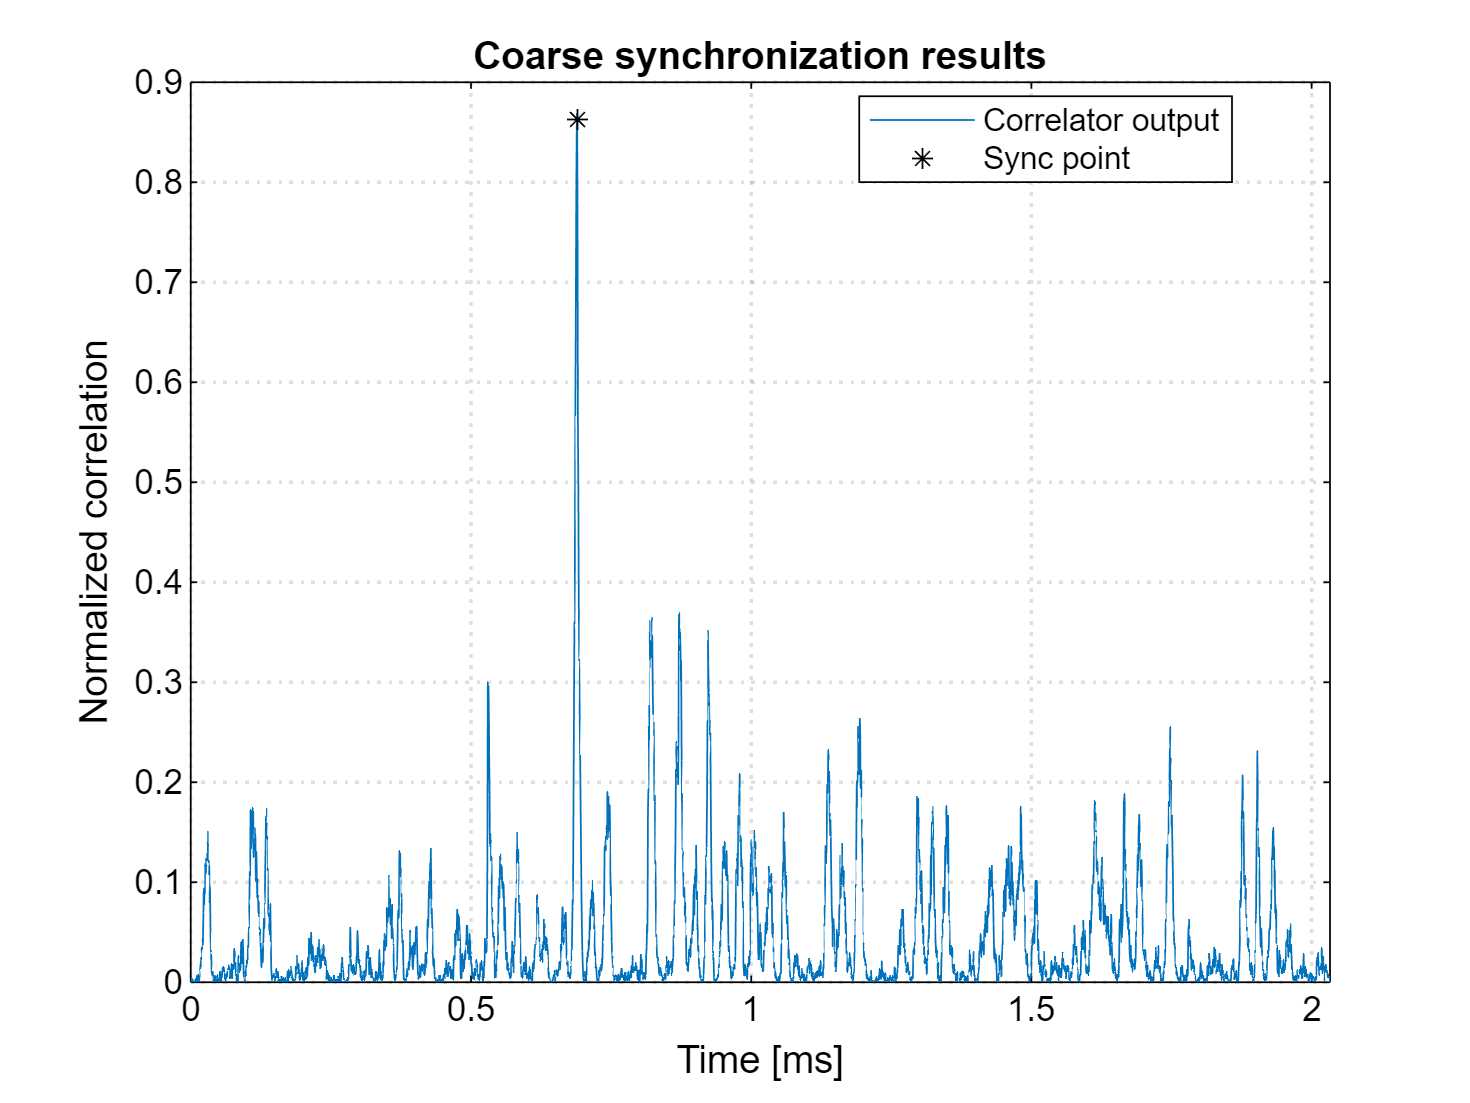

yOFDM = IQdataRX; 

% Correlation variables
L = Nidft / 2;
Nsearch = numel(IQdataRX) / 2;

% Preallocate
Pn = zeros(Nsearch, 1);
Rn = zeros(Nsearch, 1);

% Perform correlation
for n = 1:Nsearch
    for m = 0:L-1
        Pn(n)= Pn(n) + yOFDM(n+m) * conj(yOFDM(n+m+L));
        Rn(n)= Rn(n) + abs(yOFDM(n+m+L))^2;
    end
end

% Normalize correlation metric
Mn = abs(Pn).^2 ./ Rn.^2;

% Estimate the beginning sample index
thresh = 0.99;
checkVal = max(Mn) * thresh;
NstepBack = 5;

greaterThanThreshLocs = find(Mn >= checkVal);
nBegin = greaterThanThreshLocs(end);

nSync = nBegin - NstepBack;

% Estimate and correct the CFO
fcfo = -angle(Pn(nBegin)) / (2*pi*L) * fs;
yOFDM = yOFDM .* exp(-1j*2*pi*fcfo*(0:numel(yOFDM)-1)/fs).';

% Plot the correlator output
t = (0:Nsearch-1) * Ts;

figure;
grid on; box on; hold on;
ax = gca; ax.GridLineStyle = ':'; ax.GridLineWidth = 1;

plot(t*1e3, Mn)
scatter(t(nBegin)*1e3, Mn(nBegin), 'k*')

xlabel('Time [ms]')
ylabel('Normalized correlation')

xlim([0, max(t)]*1e3)

lgd = legend({'Correlator output', 'Sync point'});
lgd.Location = 'best';

title('Coarse synchronization results')

Crop the RX signal and obtain the RX polynomials *prior to* residual TO correction.

% Crop signal 
Npacket = numel(xOFDM);
yOFDMcropped = yOFDM(nSync+(0:Npacket-1));

% Remove CP and take DFT 
YwithCP = reshape(yOFDMcropped, Nidft+Ncp, []);
Y = YwithCP(1:Nidft, :);
symbolsMappedRX = fft(Y, Nidft);

% Subcarrier demapper (FM)
polyRXsync = downsample(symbolsMappedRX(1:K+1, 1), 2);
polyRXtiming = symbolsMappedRX(mod(k, Nidft) + 1, 2);
polyRXpayload = symbolsMappedRX(mod(k, Nidft) + 1, 3:end);

% Unscramble the payload coefficients
for m = 1:M-1

    % Sort scramble indices
    [~, back] = sort(scrambleIndices(:, m));

    % Perform unscrambling
    polyRXpayload(:, m) = polyRXpayload(back, m);

end

Use the timing symbol (J-BMOCZ template) to estimate and correct the residual TO.

Plot the TX and RX template transforms.

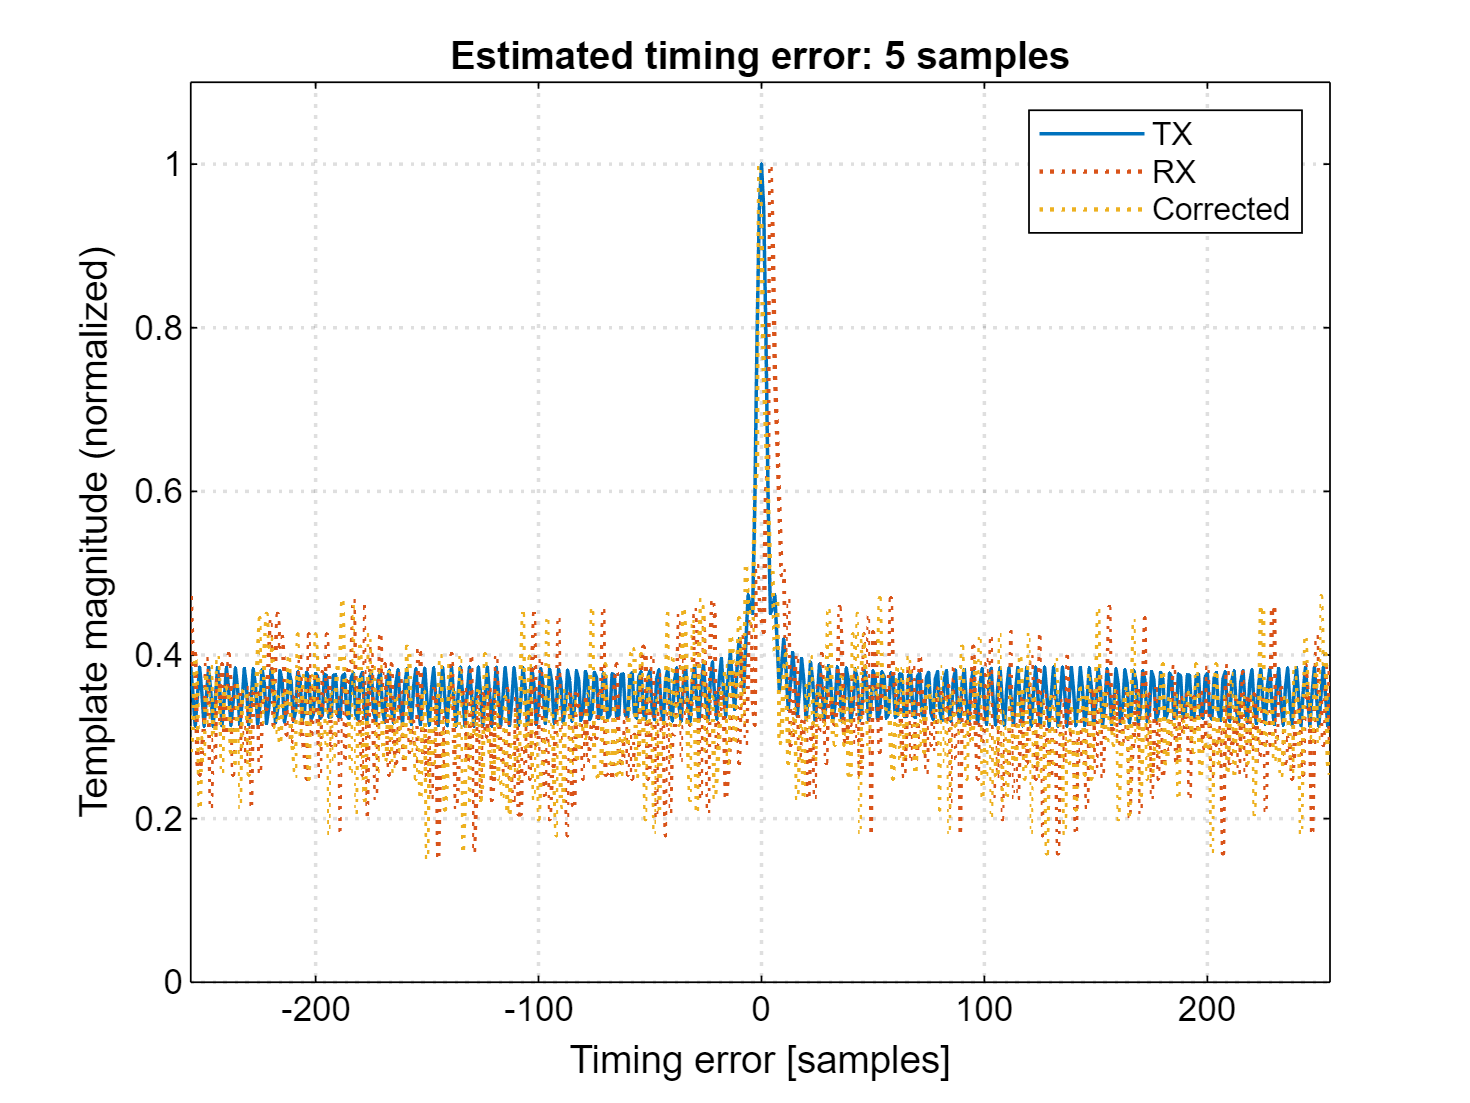

% Get RX template vector
rxTemplate = abs(Y(:, 2));

% Estimate residual TO (in samples)
innerProd = rxTemplate.' * tNmat;
[~, nMax] = max(innerProd);

shifty = -nMax + 1;
nSyncUpdated = nSync + (nMax-1);

% Normalize template vectors (for plotting)
rxTemplateNormalized = rxTemplate / max(rxTemplate);
tNnormalized = tN / max(tN); 
rxTemplateCorrectedNormalized = circshift(rxTemplateNormalized, shifty, 1);

% Plot template vectors
nPlot = -Nidft/2:Nidft/2-1;

figure;
grid on; box on; hold on;
ax = gca; ax.GridLineStyle = ':'; ax.GridLineWidth = 1;

plot(nPlot, fftshift(tNnormalized), 'LineWidth', 1)
plot(nPlot, fftshift(rxTemplateNormalized), ':', 'LineWidth', 1.25)
plot(nPlot, fftshift(rxTemplateCorrectedNormalized), ':', 'LineWidth', 1.25)

xlabel('Timing error [samples]')
ylabel('Template magnitude (normalized)')

xlim([min(nPlot), max(nPlot)])
ylim([0, 1.1])

title(['Estimated timing error: ', num2str(abs(shifty)), ' samples'])

legend({'TX', 'RX', 'Corrected'});

Crop the RX signal and obtain the RX polynomials *after* residual TO correction.

% Re-crop signal 
yOFDMcropped = yOFDM(nSyncUpdated+(0:Npacket-1));

% Remove CP and take DFT 
YwithCP = reshape(yOFDMcropped, Nidft+Ncp, []);
Y = YwithCP(1:Nidft, :);
symbolsMappedRXcorrected = fft(Y, Nidft);

% Subcarrier demapper (FM)
polyRXsyncCorrected = downsample(symbolsMappedRXcorrected(1:K+1, 1), 2);
polyRXtimingCorrected = symbolsMappedRXcorrected(mod(k, Nidft) + 1, 2);
polyRXpayloadCorrected = symbolsMappedRXcorrected(mod(k, Nidft) + 1, 3:end);

% Unscramble the payload coefficients
for m = 1:M-1

    % Sort scramble indices
    [~, back] = sort(scrambleIndices(:, m));

    % Perform unscrambling
    polyRXpayloadCorrected(:, m) = polyRXpayloadCorrected(back, m);

end

Plot the TX and RX zeros of the synchronization and timing polynomials.

**Note:** the figure may appear cramped if you are not viewing on a monitor.

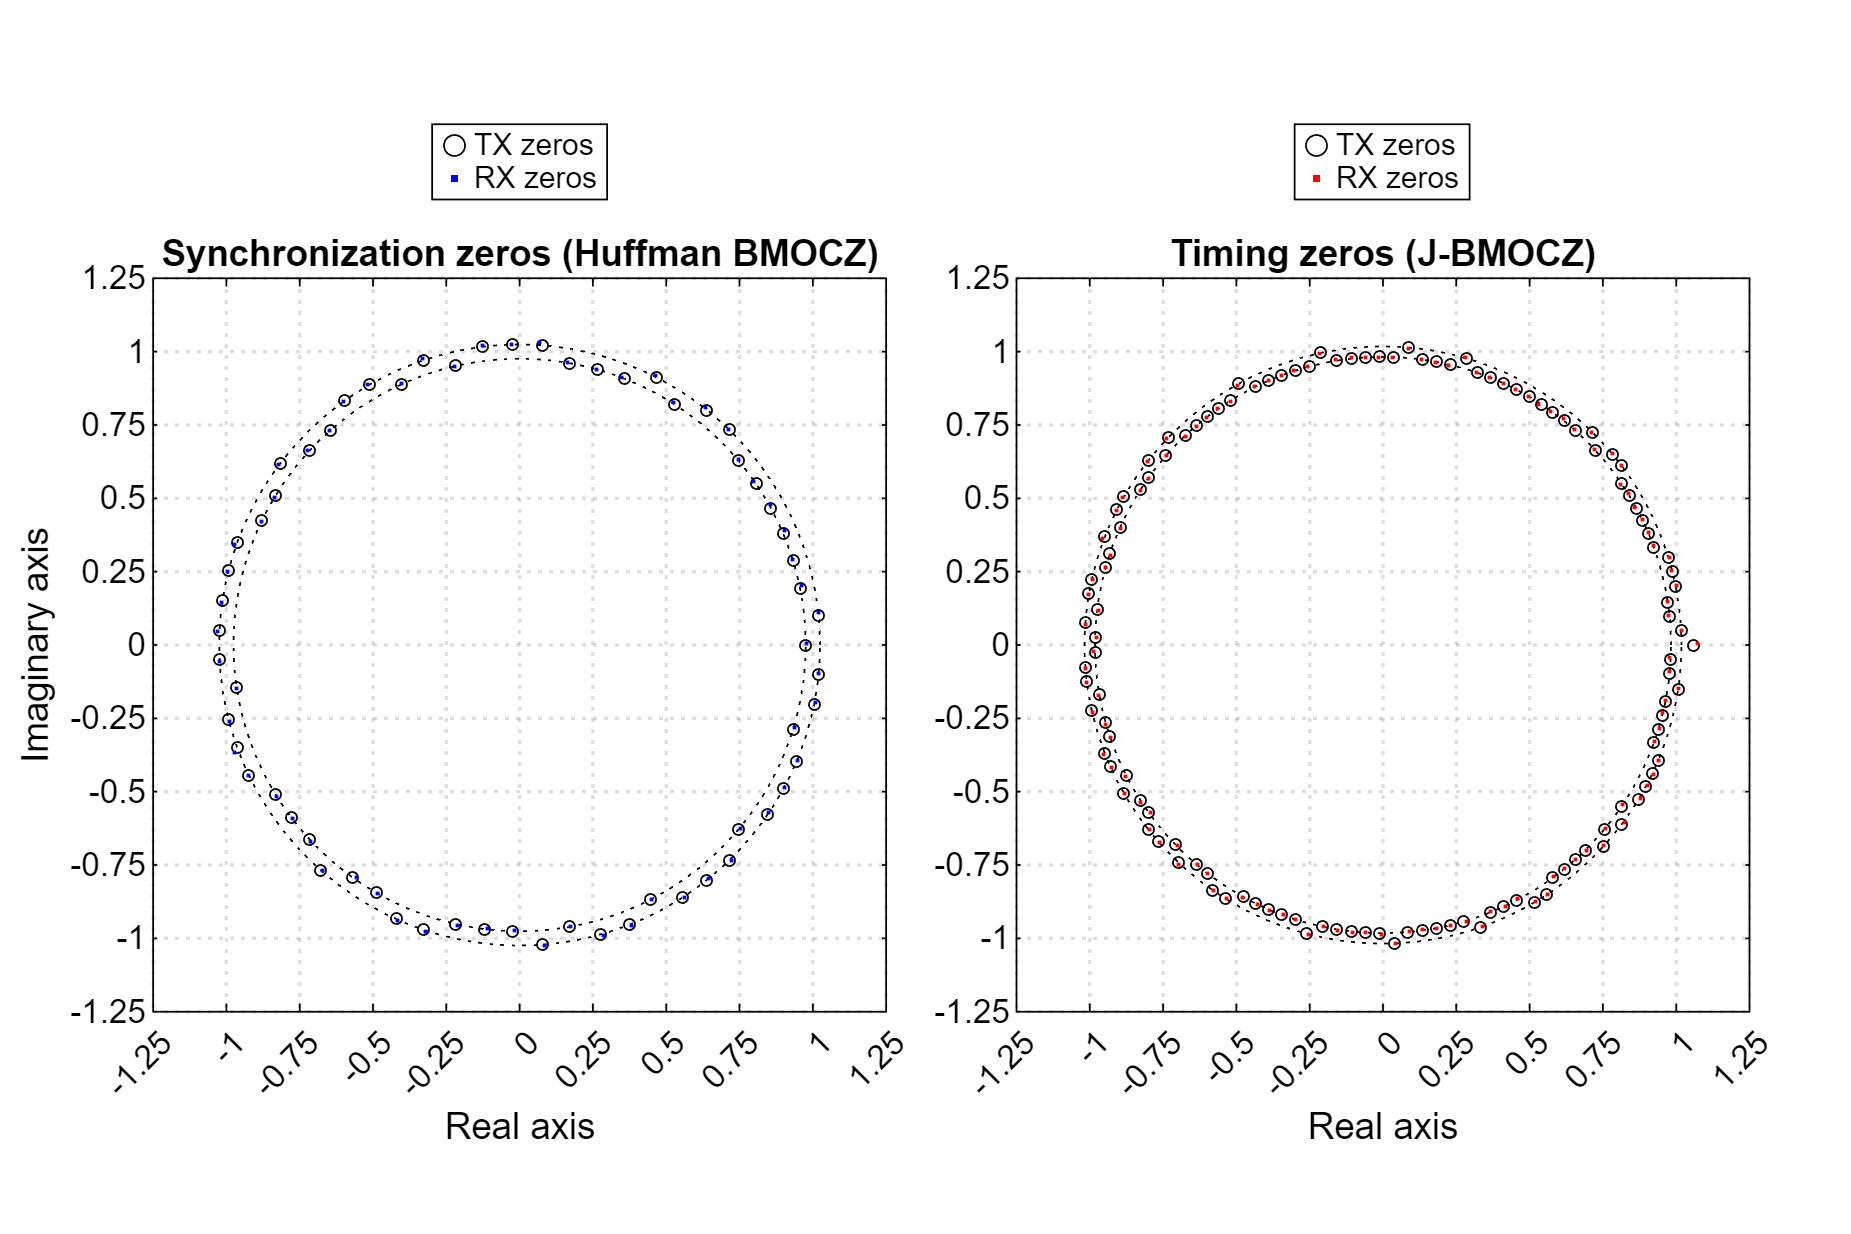

% Calculate the zeros of the RX synchronization and timing polynomials
zerosRXsync = roots(polyRXsyncCorrected);
zerosRXtiming = roots(polyRXtimingCorrected);

% Plot the TX and RX zeros
sz = 10;
theta = linspace(0, 2*pi, 100);

RouterSync = Rsync * exp(1j*theta); RinnerSync = 1/Rsync * exp(1j*theta);
RouterTiming = Rj * exp(1j*theta); RinnerTiming = 1/Rj * exp(1j*theta);

figure;
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile
grid on; box on; hold on; axis square;
ax = gca; ax.GridLineStyle = ':'; ax.GridLineWidth = 1;

plot(real(RinnerSync), imag(RinnerSync), 'k:')
plot(real(RouterSync), imag(RouterSync), 'k:')

scatter(real(zerosTXsync), imag(zerosTXsync), sz, 'ko')
scatter(real(zerosRXsync), imag(zerosRXsync), sz, 'b.', 'LineWidth', 1)

xlabel('Real axis')
ylabel('Imaginary axis')

xticks(-1.25:0.25:1.25)
yticks(-1.25:0.25:1.25)
axis([-1.25, 1.25, -1.25, 1.25])

lgd = legend({'', '', 'TX zeros', 'RX zeros'});
lgd.Location = 'northoutside';

title('Synchronization zeros (Huffman BMOCZ)')

nexttile
grid on; box on; hold on; axis square;
ax = gca; ax.GridLineStyle = ':'; ax.GridLineWidth = 1;

plot(real(RinnerTiming), imag(RinnerTiming), 'k:')
plot(real(RouterTiming), imag(RouterTiming), 'k:')

s1 = scatter(real(zerosTXtiming), imag(zerosTXtiming), sz, 'ko');
s2 = scatter(real(zerosRXtiming), imag(zerosRXtiming), sz, 'r.', 'LineWidth', 1);

xlabel('Real axis')

xticks(-1.25:0.25:1.25)
yticks(-1.25:0.25:1.25)
axis([-1.25, 1.25, -1.25, 1.25])

lgd = legend({'', '', 'TX zeros', 'RX zeros'});
lgd.Location = 'northoutside';

title('Timing zeros (J-BMOCZ)')

set(gcf, 'Position', [50 50 1200 800])  

Perform DiZeT decoding and decode the RX codewords.

% DiZeT decoding (synchronization polynomial)
mRXsync = standardDizet(polyRXsyncCorrected, Ksync, syncZeros, 0);

% DiZeT decoding (timing polynomial)
cRXtiming = standardDizet(polyRXtimingCorrected, K, jbmoczZeros, 0);

% DiZeT decoding (payload)
cRXpayload = standardDizet(polyRXpayloadCorrected, K, huffmanZeros, 0);
cRX = [cRXtiming, cRXpayload];

% (127,106)-BCH decoding
mRX = bchdec(gf(cRX.'), K, B);
mRX = double(mRX.x).';

Calculate SNR, the number of bit errors, BER, data rate, and spectral efficiency.

Print the results.

% Estimate SNR 
coeffs = symbolsMappedRXcorrected(1:2:K+1);
nulls = symbolsMappedRXcorrected(2:2:K+2);

coeffPower = mean(abs(coeffs).^2);
noisePower = mean(abs(nulls).^2);

SNR = coeffPower / noisePower;
SNRdB = 10*log10(SNR);

% Calculate the number of bit errors and BER
numBitErrors = sum(abs(mRX - mTX), 'all') + sum(abs(mRXsync - mTXsync));
BER = numBitErrors / (Nbits + Ksync);

% Calculate data rate and spectral efficiency
Tpacket = (Nsymbol)*(M+1) / fs;
R = (Nbits + Ksync) / Tpacket;
rho = R / W;

fprintf('SNR: %.2f\nNumber of bit errors: %d\nBit error rate: %.4f\nData rate: %.3f Mbps\nSpectral efficiency: %.3f bps/Hz', SNRdB, numBitErrors, BER, R/1e6, rho)

SNR: 20.75
Number of bit errors: 0
Bit error rate: 0.0000
Data rate: 3.958 Mbps
Spectral efficiency: 0.785 bps/Hz